# **Hand Tracking**

%%% Load handimage from a url 

url_img = 'http://apmonitor.com/pds/uploads/Main/hands.jpg';
outfilename = websave('hands.jpg',url_img)

outfilename = 'C:\Users\seant\MATLAB_new\hands.jpg'

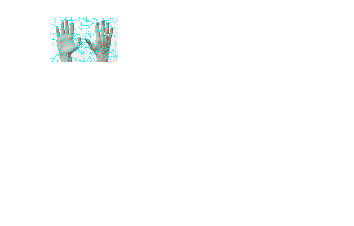


%%Read Image 
I = imread('hands.jpg');
 [L,N] = superpixels(I,1000); BW = boundarymask(L); 
 imshow(imoverlay(I,BW,'cyan'),'InitialMagnification',100);

  
figure
% Define centroid 

%%Binarize 
Ibw = imbinarize(I);

%%Fill in holes in binarized image
Ibw = imfill(Ibw,'holes');
%%%Convert binary into logical array
Ilabel = logical(Ibw);
%%% calculate coordinates for X & Y centroids
stat = regionprops(Ilabel,'centroid');

%%%Computes superpixels for the image
[L,N] = superpixels(I,500)

L =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

N = 430

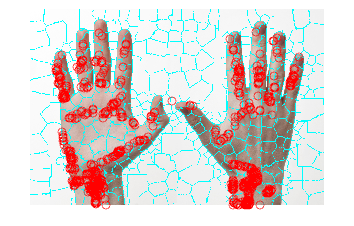

%%%%compute region boundaries for the input binary image
BW = boundarymask(L);
imshow(imoverlay(I,BW,'cyan'),'InitialMagnification',100);  hold on;
for x = 1: numel(stat)
    plot(stat(x).Centroid(1),stat(x).Centroid(2),'ro');
end

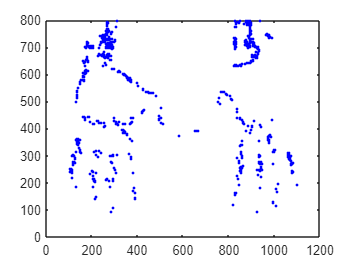

%%%TODO: Is it possible to draw a line between the dots? 
figure
for x = 1: numel(stat)
    plot(stat(x).Centroid(1),stat(x).Centroid(2),'.b-');
    drawnow;
    hold on;
end


bwskel(Ibw)

ans = 800×1200×3 logical array
ans(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

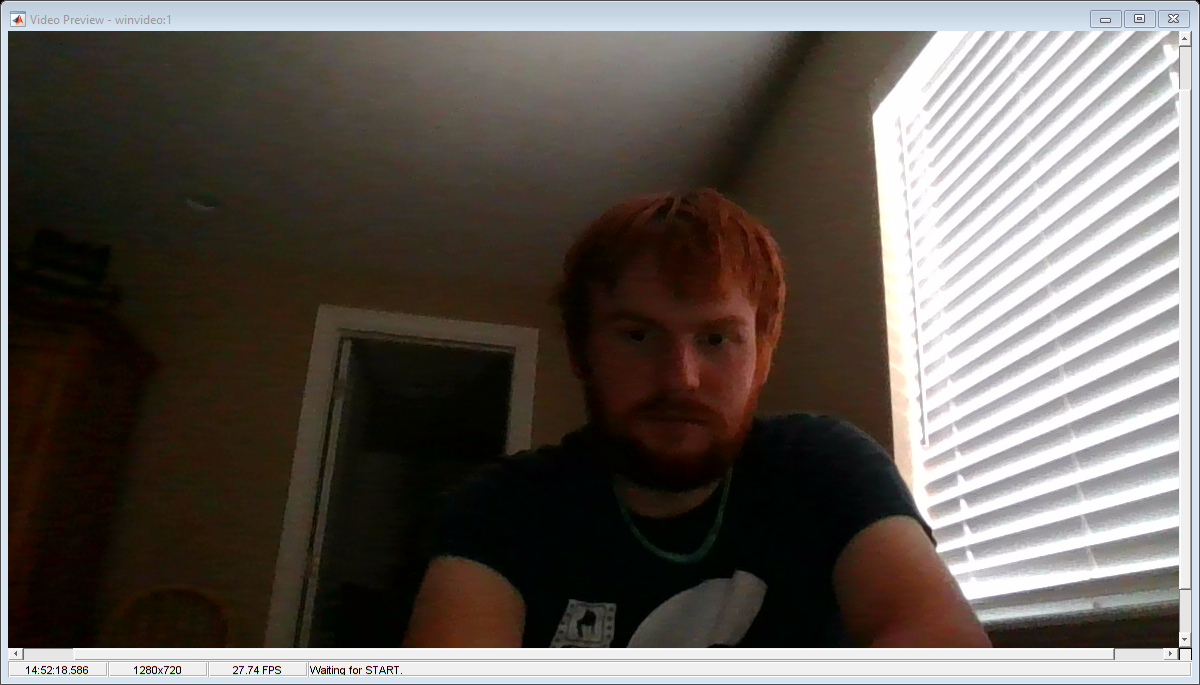

%%%%%Register Webcam with MATLAB 
%cam = webcam(1);

%%%%Connect to video camera
vid=videoinput('winvideo',1);                                             %sets videoinput to the webcam, and the webcam device 1
figure(3)
preview(vid)                                                  %displays the webcam input

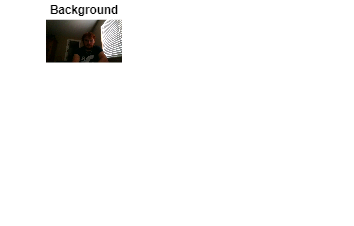


figure(1);

set(vid,'ReturnedColorspace','rgb')
pause(3);                                                                 % pause 2 seconds before snapshot of background image
IM1=getsnapshot(vid);                                                     %get snapshot from the webcam video and store to IM1 variable
figure(1);subplot(3,3,1);imshow(IM1);title('Background'); %open up a figure and show the image stored in IM1 variable

%%%%FACE Detection 
%%% Code from: https://www.mathworks.com/help/vision/ug/face-detection-and-tracking-using-live-video-acquisition.html


% Create the face detector object.
faceDetector = vision.CascadeObjectDetector();

% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);

% Create the webcam object.
cam = webcam(1);

%vid=videoinput('winvideo',1);                                             %sets videoinput to the webcam, and the webcam device 1
%figure(3)
%preview(vid)                 

% Capture one frame to get its size.
pause(2)
vid.Timeout = 20

Summary of Video Input Object Using 'Integrated Webcam'.

   Acquisition Source(s):  input1 is available.

  Acquisition Parameters:  'input1' is the current selected source.
                           10 frames per trigger using the selected source.
                           'MJPG_1280x720' video data to be logged upon START.
                           Grabbing first of every 1 frame(s).
                           Log data to 'memory' on trigger.

      Trigger Parameters:  1 'immediate' trigger(s) on START.

                  Status:  Waiting for START.
                           0 frames acquired since starting.
                           0 frames available for GETDATA.



videoFrame = getsnapshot(vid);
frameSize = size(videoFrame);

% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30]);

runLoop = true;
numPts = 0;
frameCount = 0;

while runLoop && frameCount < 400

    % Get the next frame.
    videoFrame = getsnapshot(vid);
    videoFrameGray = im2gray(videoFrame);
    frameCount = frameCount + 1;

    if numPts < 10
        % Detection mode.
        bbox = faceDetector.step(videoFrameGray);

        if ~isempty(bbox)
            % Find corner points inside the detected region.
            points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));

            % Re-initialize the point tracker.
            xyPoints = points.Location;
            numPts = size(xyPoints,1);
            release(pointTracker);
            initialize(pointTracker, xyPoints, videoFrameGray);

            % Save a copy of the points.
            oldPoints = xyPoints;

            % Convert the rectangle represented as [x, y, w, h] into an
            % M-by-2 matrix of [x,y] coordinates of the four corners. This
            % is needed to be able to transform the bounding box to display
            % the orientation of the face.
            bboxPoints = bbox2points(bbox(1, :));

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the detected face.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display detected corners.
            videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'white');
        end

    else
        % Tracking mode.
        [xyPoints, isFound] = step(pointTracker, videoFrameGray);
        visiblePoints = xyPoints(isFound, :);
        oldInliers = oldPoints(isFound, :);

        numPts = size(visiblePoints, 1);

        if numPts >= 10
            % Estimate the geometric transformation between the old points
            % and the new points.
            [xform, inlierIdx] = estgeotform2d(...
                oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
            oldInliers    = oldInliers(inlierIdx, :);
            visiblePoints = visiblePoints(inlierIdx, :);

            % Apply the transformation to the bounding box.
            bboxPoints = transformPointsForward(xform, bboxPoints);

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the face being tracked.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display tracked points.
            videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');

            % Reset the points.
            oldPoints = visiblePoints;
            setPoints(pointTracker, oldPoints);
        end

    end

    % Display the annotated video frame using the video player object.
    step(videoPlayer, videoFrame);

    % Check whether the video player window has been closed.
    runLoop = isOpen(videoPlayer);
end

% Clean up.
clear cam;
release(videoPlayer);
release(pointTracker);
release(faceDetector);

%%%%% Modify algorithm to track hands 
load('training_hands.mat')

hands = gTruth.DataSource.Source

hands = 30×1 cell array
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000002.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000003.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000004.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000005.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000007.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000008.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000009.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000010.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000013.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000021.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000020.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000016.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000038.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000039.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000048.jpg'}
    {'C:\Users\seant\MATLAB\Hands\Hands\Hand_0000093.jpg'}
    {'C:\Users\seant\MATLAB\Hand


hands_imds = imageDatastore(hands);
blds = boxLabelDatastore(gTruth.LabelData);

positiveInstances = combine(hands_imds,blds);


load('negative_sample.mat')

negativeImages = imageDatastore(gTruth.DataSource.Source);

%%%%Create Hand detector 
trainCascadeObjectDetector('hands_Detector.xml',positiveInstances,negativeImages,FalseAlarmRate=0.01,NumCascadeStages=3);


Specified outputXMLFileName hands_Detector.xml 
 already exists. What would you like to do?

 [1] Delete existing xml file and start training from the beginning

 [2] Exit this function without making any changes

Enter 1/2 in the command window [2]


Deleting output xml file hands_Detector.xml...


Automatically setting ObjectTrainingSize to [32, 32]
Using at most 30 of 30 positive samples per stage
Using at most 60 negative samples per stage

--cascadeParams--
Training stage 1 of 3
[........................................................................]
Used 30 positive and 60 negative samples
Time to train stage 1: 0 seconds

Training stage 2 of 3
[........................................................................]
Used 30 positive and 44 negative samples
Time to train stage 2: 0 seconds

Training stage 3 of 3
[....................................................


Cannot find enough samples for training. 
Training will halt and return cascade detector with 2 stages
Time to train stage 3: 1 seconds

Training complete


hands_detector = vision.CascadeObjectDetector('hands_Detector.xml');

%%%%%Redo previous function, using hands_detector instead

% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);

% Create the webcam object.
cam = webcam(1);

%vid=videoinput('winvideo',1);                                             %sets videoinput to the webcam, and the webcam device 1
%figure(3)
%preview(vid)                 

% Capture one frame to get its size.
pause(2)
vid.Timeout = 20

Summary of Video Input Object Using 'Integrated Webcam'.

   Acquisition Source(s):  input1 is available.

  Acquisition Parameters:  'input1' is the current selected source.
                           10 frames per trigger using the selected source.
                           'MJPG_1280x720' video data to be logged upon START.
                           Grabbing first of every 1 frame(s).
                           Log data to 'memory' on trigger.

      Trigger Parameters:  1 'immediate' trigger(s) on START.

                  Status:  Waiting for START.
                           0 frames acquired since starting.
                           0 frames available for GETDATA.



videoFrame = getsnapshot(vid);
frameSize = size(videoFrame);

% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30]);

runLoop = true;
numPts = 0;
frameCount = 0;

while runLoop && frameCount < 400

    % Get the next frame.
    videoFrame = getsnapshot(vid);
    videoFrameGray = im2gray(videoFrame);
    frameCount = frameCount + 1;

    if numPts < 10
        % Detection mode.
        bbox = hands_detector.step(videoFrameGray);

        if ~isempty(bbox)
            % Find corner points inside the detected region.
            points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));

            % Re-initialize the point tracker.
            xyPoints = points.Location;
            numPts = size(xyPoints,1);
            release(pointTracker);
            initialize(pointTracker, xyPoints, videoFrameGray);

            % Save a copy of the points.
            oldPoints = xyPoints;

            % Convert the rectangle represented as [x, y, w, h] into an
            % M-by-2 matrix of [x,y] coordinates of the four corners. This
            % is needed to be able to transform the bounding box to display
            % the orientation of the face.
            bboxPoints = bbox2points(bbox(1, :));

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the detected face.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display detected corners.
            videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'white');
        end

    else
        % Tracking mode.
        [xyPoints, isFound] = step(pointTracker, videoFrameGray);
        visiblePoints = xyPoints(isFound, :);
        oldInliers = oldPoints(isFound, :);

        numPts = size(visiblePoints, 1);

        if numPts >= 10
            % Estimate the geometric transformation between the old points
            % and the new points.
            [xform, inlierIdx] = estgeotform2d(...
                oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
            oldInliers    = oldInliers(inlierIdx, :);
            visiblePoints = visiblePoints(inlierIdx, :);

            % Apply the transformation to the bounding box.
            bboxPoints = transformPointsForward(xform, bboxPoints);

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the face being tracked.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display tracked points.
            videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');

            % Reset the points.
            oldPoints = visiblePoints;
            setPoints(pointTracker, oldPoints);
        end

    end

    % Display the annotated video frame using the video player object.
    step(videoPlayer, videoFrame);

    % Check whether the video player window has been closed.
    runLoop = isOpen(videoPlayer);
end

% Clean up.
clear cam;
release(videoPlayer);
release(pointTracker);
release(hands_detector);